# Color regions ROI statistics - final

This analysis contains the ROI as a binarised cluster resulting from asymmetry analysis of left vs right anterior fusiform connectivity at p=0.005, k FDR corrected.

The ROI was parcelled with AAL atal into hippocampal component and amygdala component. 

This analysis does the ame contrasts as in the main ROI analysis in those two komponents. 

THIS ANALYSIS SHOW NOTHING SIGNIFICANT SO FORGET ABOUT IT

## Load data

clear
clc
close all


cd /Users/k.siudakrzywicka/Desktop/RDS_fMRI/Controls/color_rs_connectivity/masks_for_figs

megaTable=readtable('megaTable_amyglada_hippocampus.csv'); %note that conefiles of a single beta vs 0 equas the valie of beta, so it doesn't matter if you take beta or con files

megaTable.subject = [1:20]';
megaTable_long_form_s = stack(megaTable, megaTable.Properties.VariableNames(1:end-1), 'IndexVariableName','Conditions',...
    'NewDataVariableName','Response');

cond_parts = cellfun(@(x) strsplit(x, '_'), string(megaTable_long_form_s.Conditions), 'UniformOutput', 0);

megaTable_long_form_s.ROI = cellfun(@(x) x(1),  cond_parts);
megaTable_long_form_s.Side = cellfun(@(x) x(2),  cond_parts);
megaTable_long_form_s.Conditions =  cellfun(@(x) strjoin(x(3:end),'-'), cond_parts, 'UniformOutput', 0);
megaTable_long_form_s = megaTable_long_form_s(:, [5, 4, 2, 1, 3]);

## Define contrasts and check for orthogonality

It is important than all contrasts tested in the ROI analysis are orthogonal with the contrasts used to create the ROIs (all color vs grey-scale). For the orthogonality between contrasts for ROI analysis, it is not crucial bc a seperate model is created for each contrast.

megaTable_for_contrasts = unstack(megaTable_long_form_s, 'Response', 'Conditions');


% CONTRASTS

%all color vs greyscale

c0 = [-0.5 0.33 0.33 -0.5 0.33];

%object vs abstract color
c1 = [1 -1 0.5 -1 0.5];
%object vs abstract shape (shape effect)
c2 = [-0.5 -0.5 0.33 0.33 0.33];
%congruency effect (good vs bad)
c3 = [0 0 1 0 -1];
%congruency effect (bad vs good)
c4 = [0 0 -1 0 1];

% check contrast orthogonality with c0 (all sums should = 0)
sum(c0.* c1)

ans = -2.7756e-17

sum(c0.* c2) %BABOL! check if there is any degree of acceptable orthogonality

ans = 0.1378

sum(c0.* c3)

ans = 0


% check for orthogonality between ROI contrasts
sum(c1.* c2)

ans = 0

sum(c1.* c3)

ans = 0

sum(c1.* c4)

ans = 0

sum(c2.* c3)

ans = 0

sum(c2.* c4)

ans = 0

sum(c3.* c4)

ans = -2


%Psin = sum(cn * condition mean per subj)
megaTable_for_contrasts.psi1 = sum(c1.*megaTable_for_contrasts{:, 4:8}, 2);
megaTable_for_contrasts.psi2 = sum(c2.*megaTable_for_contrasts{:, 4:8}, 2);
megaTable_for_contrasts.psi3 = sum(c3.*megaTable_for_contrasts{:, 4:8}, 2);
megaTable_for_contrasts.psi4 = sum(c4.*megaTable_for_contrasts{:, 4:8}, 2);

contrasts_within_factors = unique(megaTable_for_contrasts(:, 2), 'stable');


Let's plot the activity in each of the condition that interests us by Side (separate plots) and ROI (x axis)

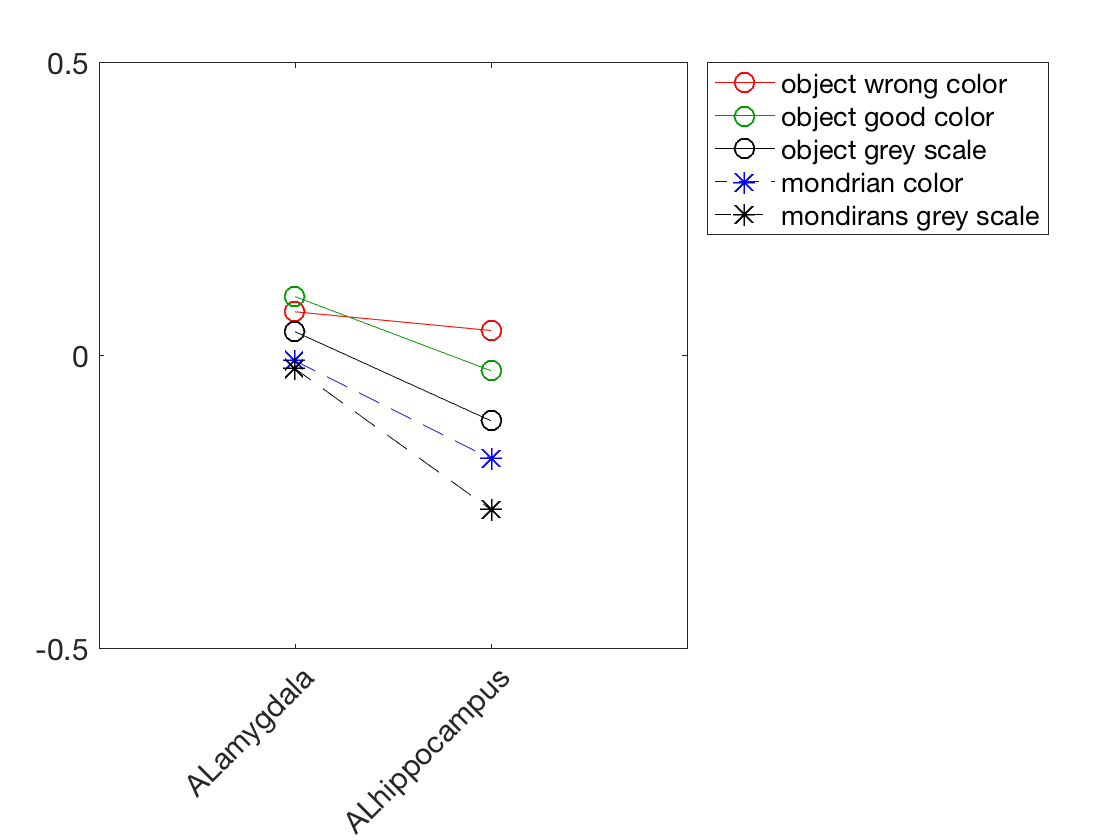

data_to_plot = megaTable_for_contrasts(:, 1:8);

[g, i1] = findgroups(data_to_plot.ROI);
to_plot = splitapply(@mean, data_to_plot{:,4:end},g);
to_plot = to_plot(:, [5 3 4 2 1]);

leg = data_to_plot.Properties.VariableNames(4:end);
    leg = strrep (leg, '_', ' ');
    leg = string(leg ([5 3 4 2 1]));
    
figure

    h = plot(to_plot);
    
    set(h,{'Marker'},{'o';'o';'o'; '*'; '*'})
    set(h,'MarkerSize',10)
    set(h,{'Color'},{'r'; [0 153 0]./255; 'k';'b'; 'k' })
    set(h,{'LineStyle'},{'-';'-';'-'; '--'; '--'})

    %title(i1{1} , 'fontsize',20)
    lgd = legend(leg, 'Location', 'bestoutside');
    xlim([0 3]);
    ylim ([-0.5 0.5])
    xticks(1:1:2);
    labels = i1';
    xticklabels(labels);
    xtickangle(45);
    set(gca, 'FontSize', 15)

## The shape x color interaction

This contrast weights correspond to the situation where signals for (object good color+object bad color) - object GS are greated than signals for mondrian color vs mondrian GS. This is why the positive values of thi contrasts should be expected in object color region rather than abstract color region. 

%prepare data set for analysis
psi1  = unstack (megaTable_for_contrasts(:, [2 3 9]), 'psi1', 'ROI');

%psi1.Properties.VariableNames(2:end) = strcat('psi1_', psi1.Properties.VariableNames(2:end));

%fir the model with firrm
objectColor_rm = fitrm(psi1,'ALamygdala-ALhippocampus~1',...
    'WithinDesign',contrasts_within_factors);

% run ANOVA
objectColor_anova = ranova(objectColor_rm, 'WithinModel','ROI' )

objectColor_anova = 4×8 table
                         SumSq       DF      MeanSq          F         pValue     pValueGG    pValueHF    pValueLB
                       __________    __    __________    __________    _______    ________    ________    ________

    (Intercept)          0.044052     1      0.044052        0.2454    0.62601    0.62601     0.62601     0.62601 
    Error                  3.4106    19       0.17951                                                             
    (Intercept):ROI    3.8786e-06     1    3.8786e-06    0.00010089    0.99209    0.99209     0.99209     0.99209 
    Error(ROI)            0.73041    19      0.038443 

nothing significant

## The shape effect

%prepare data set for analysis
psi2 = unstack (megaTable_for_contrasts(:, [1 2 3 10]), 'psi2', 'ROI');

% fir fm model
shape_rm = fitrm(psi2,'ALamygdala-ALhippocampus~1',...
    'WithinDesign',contrasts_within_factors);
%ANOVA
shape_anova = ranova(shape_rm, 'WithinModel','ROI' )

shape_anova = 4×8 table
                        SumSq     DF     MeanSq       F        pValue     pValueGG    pValueHF    pValueLB
                       _______    __    ________    ______    ________    ________    ________    ________

    (Intercept)        0.75777     1     0.75777    7.0798    0.015439    0.015439    0.015439    0.015439
    Error               2.0336    19     0.10703                                                          
    (Intercept):ROI    0.10301     1     0.10301    2.2474     0.15027     0.15027     0.15027     0.15027
    Error(ROI)         0.87082    19    0.045832                                                    

## Congruency effect

Last but not least, let's see if any of our ROIs differentiate between congruent or incongruent colors. Let's strat with regions that show preference towards congruent colors.

%prepare dataset
tmp = unstack (megaTable_for_contrasts(:, [1 2 3 11]), 'psi3', 'ROI');
psi3 = unstack (tmp, tmp.Properties.VariableNames(3:end), 'Side');
psi3.Properties.VariableNames(2:end) = strcat('psi3_', psi3.Properties.VariableNames(2:end));

%fit rm
congruency_rm = fitrm(psi3,'psi3_anteriorFusiform_left-psi3_occipitalFusiform_right~1',...
    'WithinDesign',contrasts_within_factors);

%run ANOVA
congruency_anova = ranova(congruency_rm, 'WithinModel','Side*ROI' )

congruency_anova = 4×8 table
                        SumSq      DF     MeanSq       F       pValue     pValueGG    pValueHF    pValueLB
                       ________    __    ________    ______    _______    ________    ________    ________

    (Intercept)        0.018287     1    0.018287    0.3081    0.58533    0.58533     0.58533     0.58533 
    Error                1.1278    19    0.059357                                                         
    (Intercept):ROI    0.089127     1    0.089127    2.5345    0.12789    0.12789     0.12789     0.12789 
    Error(ROI)          0.66815    19    0.035166                                              

Conruency_margMeans_x_Side_by_ROI = margmean(congruency_rm, 'ROI')

Conruency_margMeans_x_Side_by_ROI = 2×5 table
          ROI            Mean        StdErr       Lower       Upper  
    _______________    _________    ________    _________    ________

    'ALamygdala'        0.025822    0.044559    -0.067442     0.11909
    'ALhippocampus'    -0.068585    0.052351     -0.17816    0.040986


There is a significant preference towards congruent color in the letf early occipital cortex. The left anterior fusiform seems to respond more strongly to the incongruent color (negative mean).

Let's se, with post-hoc tests, if there are any cross-hemispheric differences between ROIs.

post_hoc_congruency_anova_Side_by_ROI = multcompare(congruency_rm,'ROI')

post_hoc_congruency_anova_Side_by_ROI = 2×7 table
         ROI_1              ROI_2         Difference     StdErr     pValue       Lower       Upper  
    _______________    _______________    __________    ________    _______    _________    ________

    'ALamygdala'       'ALhippocampus'     0.094407     0.059301    0.12789    -0.029711     0.21852
    'ALhippocampus'    'ALamygdala'       -0.094407     0.059301    0.12789     -0.21852    0.029711
